clear all ;

%read data in table tbl
tbl = readtable( "highpT_all_tabs.dat", "Delimiter",'\t','TextType','string') 

tbl = 200×101 table
    id     norm      tau0       etas      CH_RAA_1020_8    CH_RAA_1020_9    CH_RAA_1020_10    CH_RAA_1020_12    CH_RAA_1020_14    CH_RAA_1020_16    CH_RAA_1020_18    CH_RAA_1020_21    CH_RAA_1020_24    CH_RAA_1020_28    CH_RAA_1020_33    CH_RAA_1020_42    CH_RAA_2030_8    CH_RAA_2030_9    CH_RAA_2030_10    CH_RAA_2030_12    CH_RAA_2030_14    CH_RAA_2030_16    CH_RAA_2030_18    CH_RAA_2030_21    CH_RAA_2030_24    CH_RAA_2030_28    CH_RAA_2030_33    CH_RAA_2030_42    CH_RAA_3040_8    


%extract data which correspond to 3 predictors as a matrix
predictor_data = tbl{:,2:4} ;

[ predictor_data_norm , mean_predictor_data , std_predictor_data ] = normalize( predictor_data )   ;


Parameters that define scaling of the original predictors (input variables):

load gprMdl_highpt_PC_1_all.mat

load gprMdl_highpt_PC_2_all.mat

load gprMdl_highpt_PC_3_all.mat



load modeling_errors_highpT.mat  
% 
% mod_err_PC_1  
% 
% mod_err_PC_2  
% 
% mod_err_PC_3

load highpT_exp_data_PC.mat  

%PC_1_exp  

%PC_2_exp  

%PC_3_exp  

%PC_1_exp_err   

%PC_2_exp_err   

%PC_3_exp_err   

err_PC_1 = sqrt( PC_1_exp_err.^2 + mod_err_PC_1.^2 )

err_PC_1 = 0.6528


err_PC_2 = sqrt( PC_2_exp_err.^2 + mod_err_PC_2.^2 )

err_PC_2 = 0.6993


err_PC_3 = sqrt( PC_3_exp_err.^2 + mod_err_PC_3.^2 )

err_PC_3 = 0.6712


%min_hyperparameters_data = 60.8761    0.2011    0.0204

%max_hyperparameters_data = 359.4388    1.1986    0.1995

lb = [61, 0.2, 0.02 ] ;

ub = [359, 1.2, 0.2 ] ;

lb_stan = ( lb - mean_predictor_data )./std_predictor_data

lb_stan =    -1.7141   -1.7270   -1.7274



ub_stan = ( ub - mean_predictor_data )./std_predictor_data

ub_stan =     1.7159    1.7269    1.7286




x0 = [300,  0.2 ,  0.3 ] ;

x0_stan = ( x0 - mean_predictor_data )./std_predictor_data

x0_stan =     1.0368   -1.7270    3.6487




highpt_pred = @(x)[ ( predict( gprMdl_highpt_PC_1_all ,x) - PC_1_exp )/err_PC_1 ; ( predict( gprMdl_highpt_PC_2_all ,x) - PC_2_exp )/err_PC_2 ; ( predict( gprMdl_highpt_PC_3_all , x ) - PC_3_exp )/err_PC_3 ]  ;

x_stan = lsqnonlin( highpt_pred,x0_stan,lb_stan,ub_stan ) ;


Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>



x = x_stan.*std_predictor_data + mean_predictor_data   

x =   142.9553    1.0213    0.1830


Generating Monte Carlo samples from drows according to errors:

n = 1000  ;

N = 100  ;

x0_mat = repmat(lb,N,1) + (repmat(ub,N,1)-repmat(lb,N,1)).*rand(N,3)

x0_mat =   347.5890    0.4457    0.1646
  285.9869    1.1165    0.0743
  188.2205    0.7865    0.0279
  209.0281    0.2111    0.0473
   99.5683    0.9981    0.0470
  235.2681    0.2873    0.1325
  259.3096    0.6688    0.0591
  305.9594    1.1860    0.0999
  351.6712    0.7302    0.0613
  289.1069    0.5527    0.1638



param_mat = []   ;

for i = 1:N

    x0_stan = x0_mat(i,:) ;

    for j = 1:n

        PC_1_pert = PC_1_exp + random('Normal',0,err_PC_1) ;

        PC_2_pert = PC_2_exp + random('Normal',0,err_PC_2) ;

        PC_3_pert = PC_3_exp + random('Normal',0,err_PC_3) ;

        param_mat = [ param_mat  ; [ x0_stan PC_1_pert PC_2_pert PC_3_pert ]  ] ;

    end

end

param_freq_mat = []


param_freq_mat =

     []




parfor i = 1:(N*n)

    x0_stan = param_mat(i,1:3)  ;

    PC_1_pert = param_mat(i,4)     ;

    PC_2_pert = param_mat(i,5)     ;

    PC_3_pert = param_mat(i,6)    ;

    highpT_pred = @(x)[ ( predict( gprMdl_highpt_PC_1_all ,x) - PC_1_pert )/err_PC_1 ; ( predict( gprMdl_highpt_PC_2_all ,x) - PC_2_pert )/err_PC_2 ; ( predict( gprMdl_highpt_PC_3_all , x ) - PC_3_pert )/err_PC_3 ]  ;

    x_stan = lsqnonlin( highpT_pred ,x0_stan,lb_stan,ub_stan ) ;

    x = x_stan.*std_predictor_data + mean_predictor_data    ;

    param_freq_mat = [ param_freq_mat ; x ]                                   ;

end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<

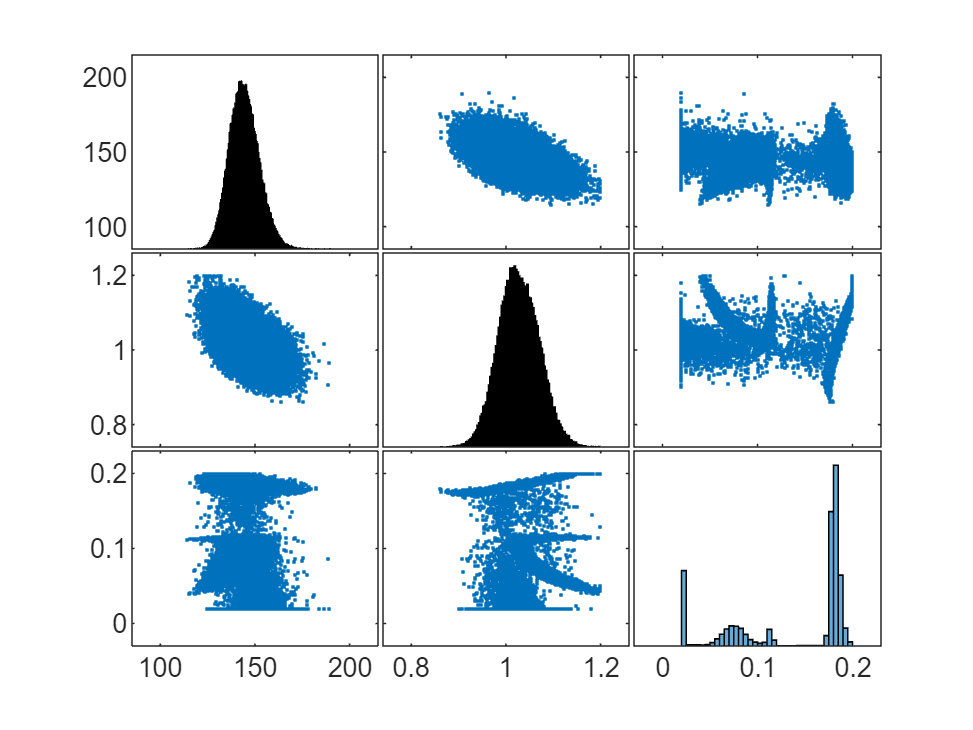


plotmatrix( param_freq_mat )  ;


param_freq_mat_weighted = param_freq_mat

param_freq_mat_weighted =   142.4801    1.0688    0.1904
  131.9061    1.0482    0.1845
  136.2667    1.0859    0.1914
  140.5031    1.0974    0.1944
  155.3701    0.9586    0.1772
  146.2382    1.0306    0.1849
  143.1248    0.9800    0.1781
  150.3722    0.9465    0.1758
  133.6483    1.0670    0.1126
  144.2435    1.0421    0.1862



save param_freq_mat_weighted_highpT.mat  param_freq_mat_weighted

%x_opt = [ 101.6  0.905  0.16 ]


Here save the maximum and errors to use them in Hamiltonian MC:

param_freq_median =  median( param_freq_mat )  ;

param_freq_std = std( param_freq_mat  )   ;

param_freq_median_weight  = param_freq_median

param_freq_median_weight =   144.0033    1.0260    0.1786



param_freq_std_weight = param_freq_std

param_freq_std_weight =     7.9098    0.0425    0.0612



save param_freq_optimization_highpT_weight.mat    param_freq_median_weight   param_freq_std_weight   ;

%here should extract maximum and standard deviation for each of the three
%parameters.